# Create orthogonal basis set for $R^n$ space

Method 1:  Sample sines and cosine waves of consecutive integer wave numbers .

Wave numbers for cosine functions are  0,1,2,..,$\left\lfloor \frac{n}{2}\right\rfloor$ 

Wave numbers for sine functions  are  

                                   1,..,$\left\lfloor \frac{n}{2}\right\rfloor$if n is odd 

                                     1,..,$\left\lfloor \frac{n}{2}\right\rfloor -1\;,\mathrm{if}\;n\;\mathrm{is}\;\mathrm{even}$

**Example 1**. Find wave numbers required  for cos and sine for n=5.

    $\left\lfloor \frac{5}{2}\right\rfloor$=2 . 

   wave numbers for cosine functions are : 0,1,2

   wave numbers for sine functions are : 1,2

Step 1: Sample the range (0,2$\left.\pi \right)$into n numbers at the   

             intervals  of $\frac{2\pi }{n}$ . 

             Start  from 0 and end at $2\pi -\frac{2\pi }{n}$    

    Matlab commands : 

             1)  theta=(0:n-1)*2*pi/n

             2)  theta=linspace(0:2*pi,n+1);

                  theta=theta(1:n) 

              3) theta=0 : 2*pi/n : 2*pi-2*pi/n

    Step 2 :  Create bases as column vectors. Normalize each  

                   column vector  

                 Matlab code : using outer product

                 theta=theta(:);  % convert into column vector

                 wn_cos=0:floor(n/2);

                  wn_sin=0:floor(n/2); or wn_sin=0:floor(n/2)-1

                  B=[cos(theta*wn_cos)  sin(theta*wn_sin)];

                  B=B./norm(B);    % normalize each column 

n=5;
theta=(0:n-1)*2*pi/n;
theta=theta(:);  % convert into column vector
wn_cos=0:floor(n/2);% wave numbers for Cosine
 if mod(n,2)==1   % if n is odd 
 wn_sin=1:floor(n/2); % wave numbers for sine
 else
 wn_sin=1:floor(n/2)-1;     % if n is odd 
 end 
                  
 B=[cos(theta*wn_cos)  sin(theta*wn_sin)]    %append

B =     1.0000    1.0000    1.0000         0         0
    1.0000    0.3090   -0.8090    0.9511    0.5878
    1.0000   -0.8090    0.3090    0.5878   -0.9511
    1.0000   -0.8090    0.3090   -0.5878    0.9511
    1.0000    0.3090   -0.8090   -0.9511   -0.5878


                  B=B./norm(B)    % normalize each column

B =     0.4472    0.4472    0.4472         0         0
    0.4472    0.1382   -0.3618    0.4253    0.2629
    0.4472   -0.3618    0.1382    0.2629   -0.4253
    0.4472   -0.3618    0.1382   -0.2629    0.4253
    0.4472    0.1382   -0.3618   -0.4253   -0.2629


                   round(B*B')

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


                   round(B'*B)

ans =      1     0     0     0     0
     0     0     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     0


Problem 1. Represent vector $x$ =[ 1 2 3 4 5]' using Fourier bases

                Steps. tuple size of x is 5. Create 5x5 basis Matrix B and take dot product  with each basis vector. Let X be  vecor of Coeeficients. 


$$X=B^T x$$


 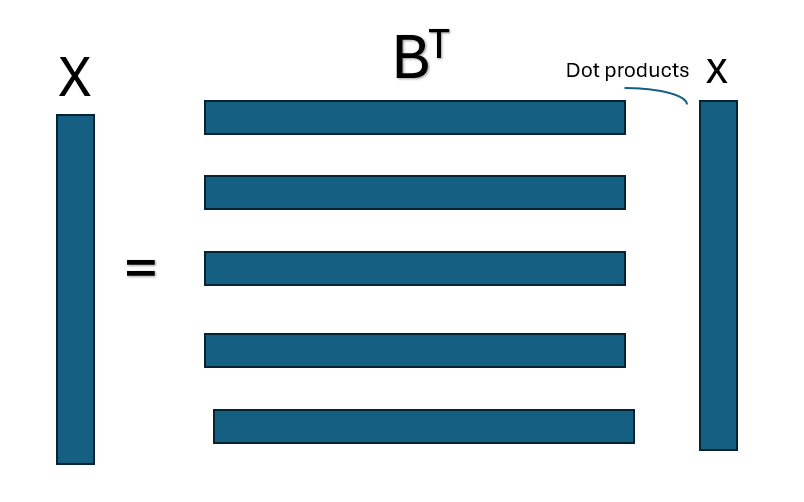

x=X(1)*B(:,1)+X(2)*B(:,2)+X(3)*B(:,3)+X(4)*B(:,4)+X(5)*B(:,5)

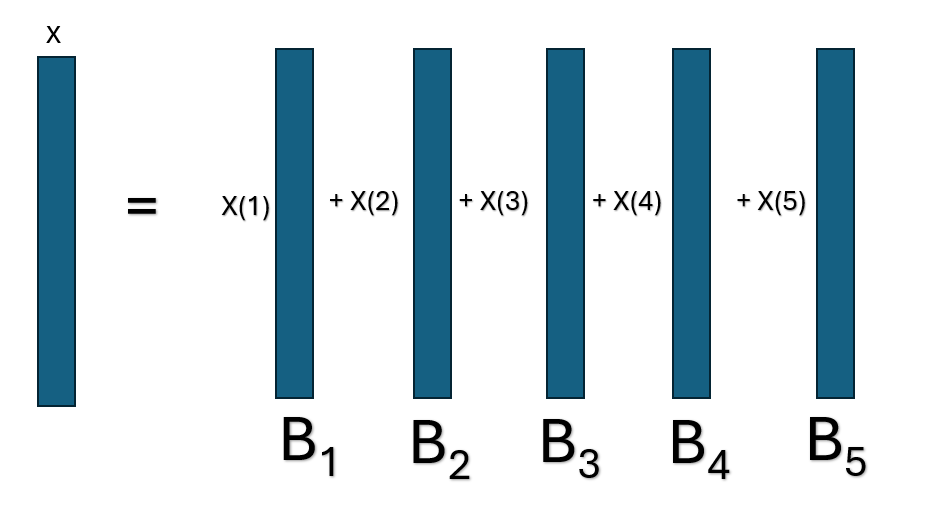


$$x=\mathrm{BX}$$


n=5;
theta=(0:n-1)*2*pi/n;
theta=theta(:);  % convert into column vector
wn_cos=0:floor(n/2);% wave numbers for Cosine
 if mod(n,2)==1   % if n is odd 
 wn_sin=1:floor(n/2); % wave numbers for sine
 else
 wn_sin=1:floor(n/2)-1;     % if n is even 
 end 
                  
 B=[cos(theta*wn_cos)  sin(theta*wn_sin)]    %append

B =     1.0000    1.0000    1.0000         0         0
    1.0000    0.3090   -0.8090    0.9511    0.5878
    1.0000   -0.8090    0.3090    0.5878   -0.9511
    1.0000   -0.8090    0.3090   -0.5878    0.9511
    1.0000    0.3090   -0.8090   -0.9511   -0.5878


for i=1:n
normB(i)=norm(B(:,i)); % find norm of each column
end 
B=B./normB

B =     0.4472    0.6325    0.6325         0         0
    0.4472    0.1954   -0.5117    0.6015    0.3717
    0.4472   -0.5117    0.1954    0.3717   -0.6015
    0.4472   -0.5117    0.1954   -0.3717    0.6015
    0.4472    0.1954   -0.5117   -0.6015   -0.3717


 B'*B

ans =     1.0000   -0.0000    0.0000    0.0000    0.0000
   -0.0000    1.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    1.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000    1.0000


 x=(1:5)';
 X=B'*x

X =     6.7082
   -1.5811
   -1.5811
   -2.1763
   -0.5137


 % Verify
 B*X      % must be x   

ans =     1.0000
    2.0000
    3.0000
    4.0000
    5.0000


Method 2. Discrete Cosine Basis set

Method 1:  Sample  cosine waves of consecutive integer muliples of (1/2) wave numbers .

Wave numbers for cosine functions are ( 0,1,2,..,n-1)*1/2 